# Method#2 Random Radial Point

## 隨機半徑法

畫出單位圓和內接正三角形

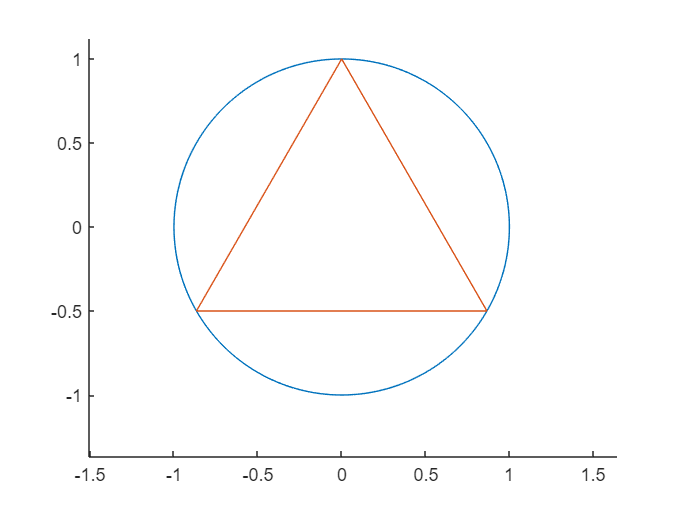

r = 1;
syms x y
clf

hold on;
fimplicit(x^2+y^2 == r^2, [-2 2, -2 2]);
t = [0;1];
R = [cos(2*pi/3) -sin(2*pi/3); sin(2*pi/3) cos(2*pi/3)];
t = [t R*t R^2*t t]';
plot(t(:,1),t(:,2))
axis equal;
hold off;

## Prob

$b(chord)$：隨機弦長

$a=\sqrt 3
$：正三角形邊長

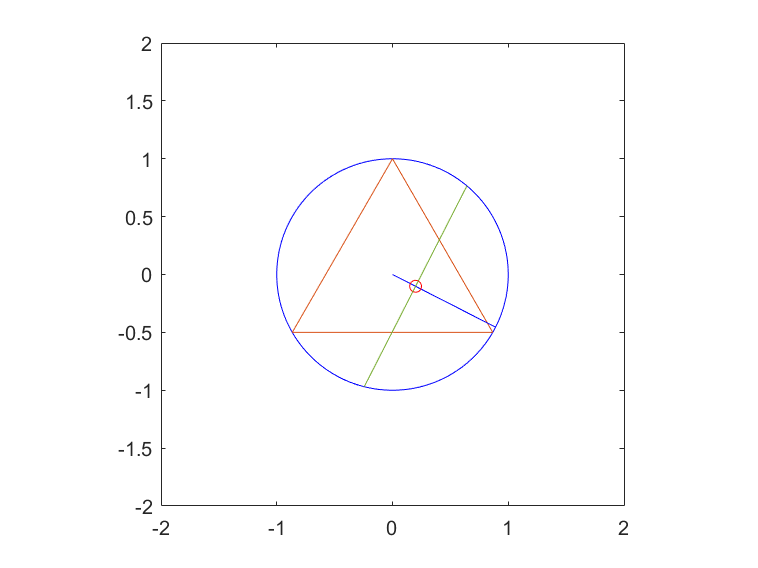

a = sqrt(3);
count = 0;
N = 10;
num = 360;
theta = linspace(0, 2*pi, num);

for i=1:N
    angle = theta(randi(num));
    p = [cos(angle) sin(angle)];
    rp = p*rand(1);
    m = -(p(1)/p(2)); % vertical slope of p

    % Calculate the length of chord
    h = sum(rp.^2);
    chord = sqrt(1 - h) * 2; % equal to b
    if chord > a 
        count = count + 1;
    end

    % Calculate the 2 points of intersection of chord and circle
    vec = [1 m];
    vec = vec./norm(vec); % normalize
    vec = vec.*(chord/2);
    p1 = rp+vec;
    p2 = rp-vec;

    % Plot
    
    fimplicit(x^2+y^2 == r^2, [-2 2, -2 2], 'b-');
    hold on

    plot(t(:,1),t(:,2));
    plot([0 p(1)], [0 p(2)], 'b-');
    plot(rp(1), rp(2), 'ro');
    plot([p1(1) p2(1)], [p1(2) p2(2)])

    axis equal 
    hold off
    pause(0.01);
end
xlim([-2 2]);
ylim([-2 2]);


prob = count/N

prob = 0.5700